# Image Processing

## Import Image

image = imread('Data/t2.jpg');
background = imread('Data/backGround.jpg');

## Show Background & Image

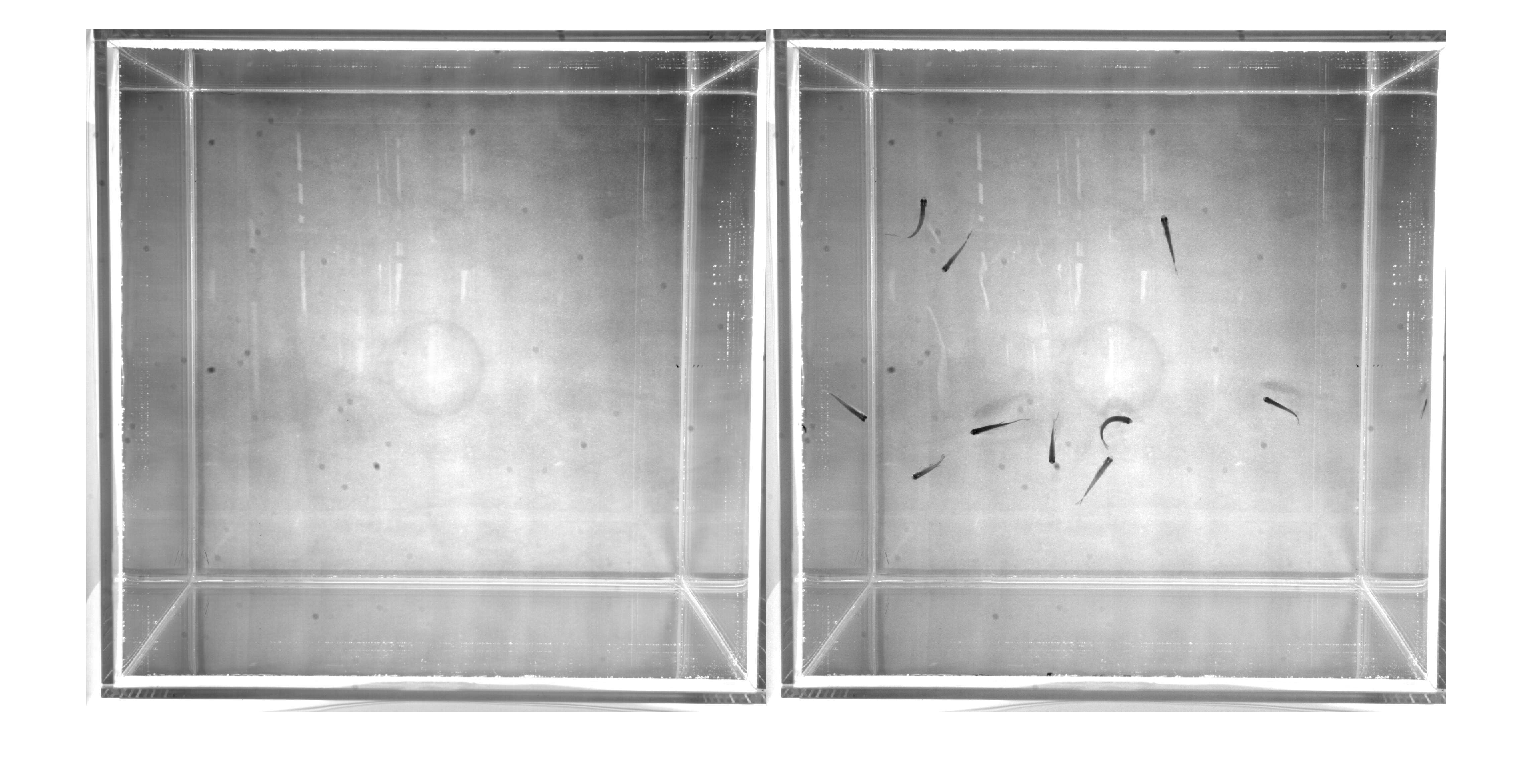

imshowpair(background,image,'montage'); 

## Show a histogram of image contents

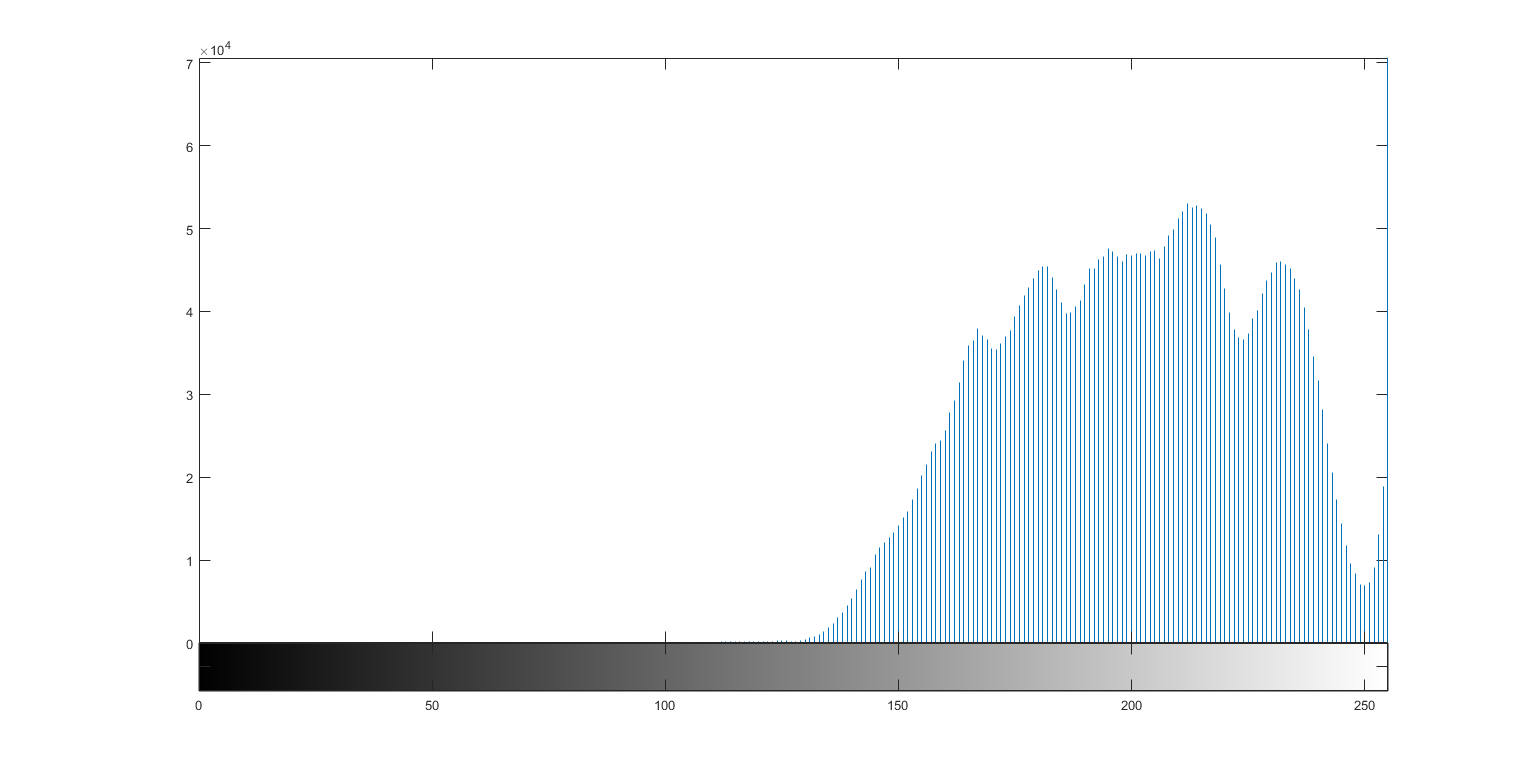

imhist(image);

## Subtract Background & Fill holes

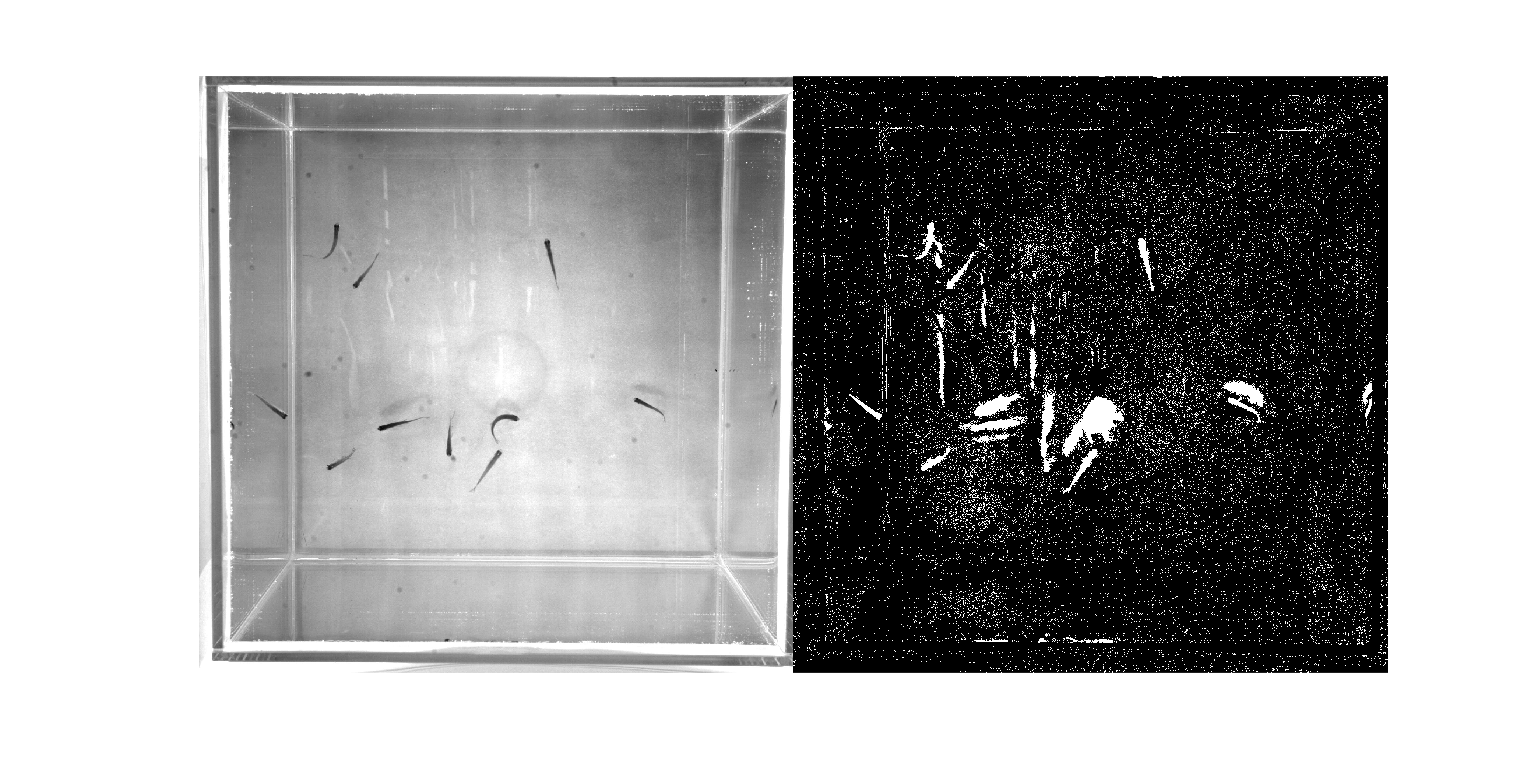

image1 = background(:,:) - image(:,:) > 3;
image2 = imfill(image1,'holes');
imshowpair(image,image2,'montage');

## Remove Small Objects

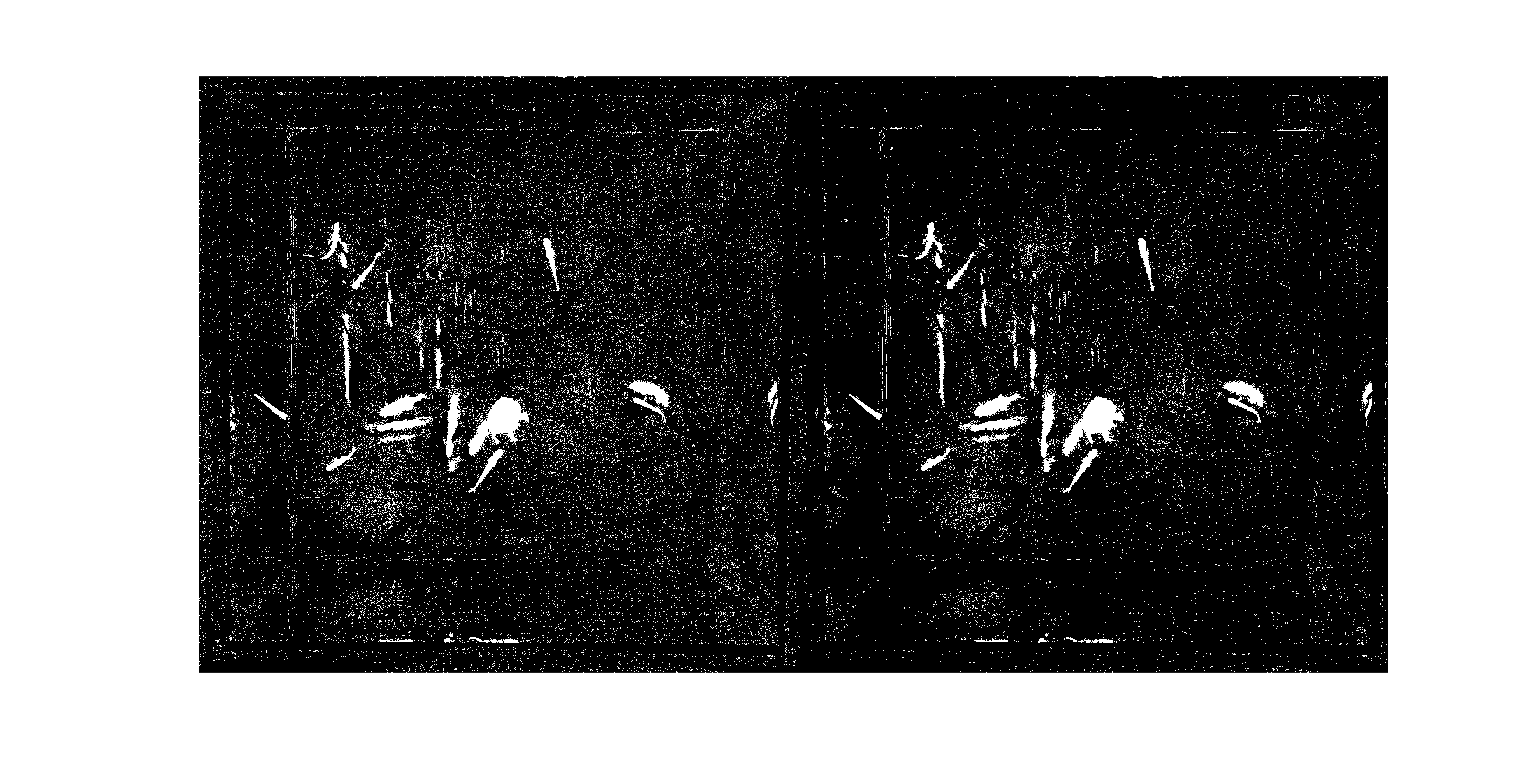

image3 = bwareaopen(image2,5);
imshowpair(image2,image3,'montage');

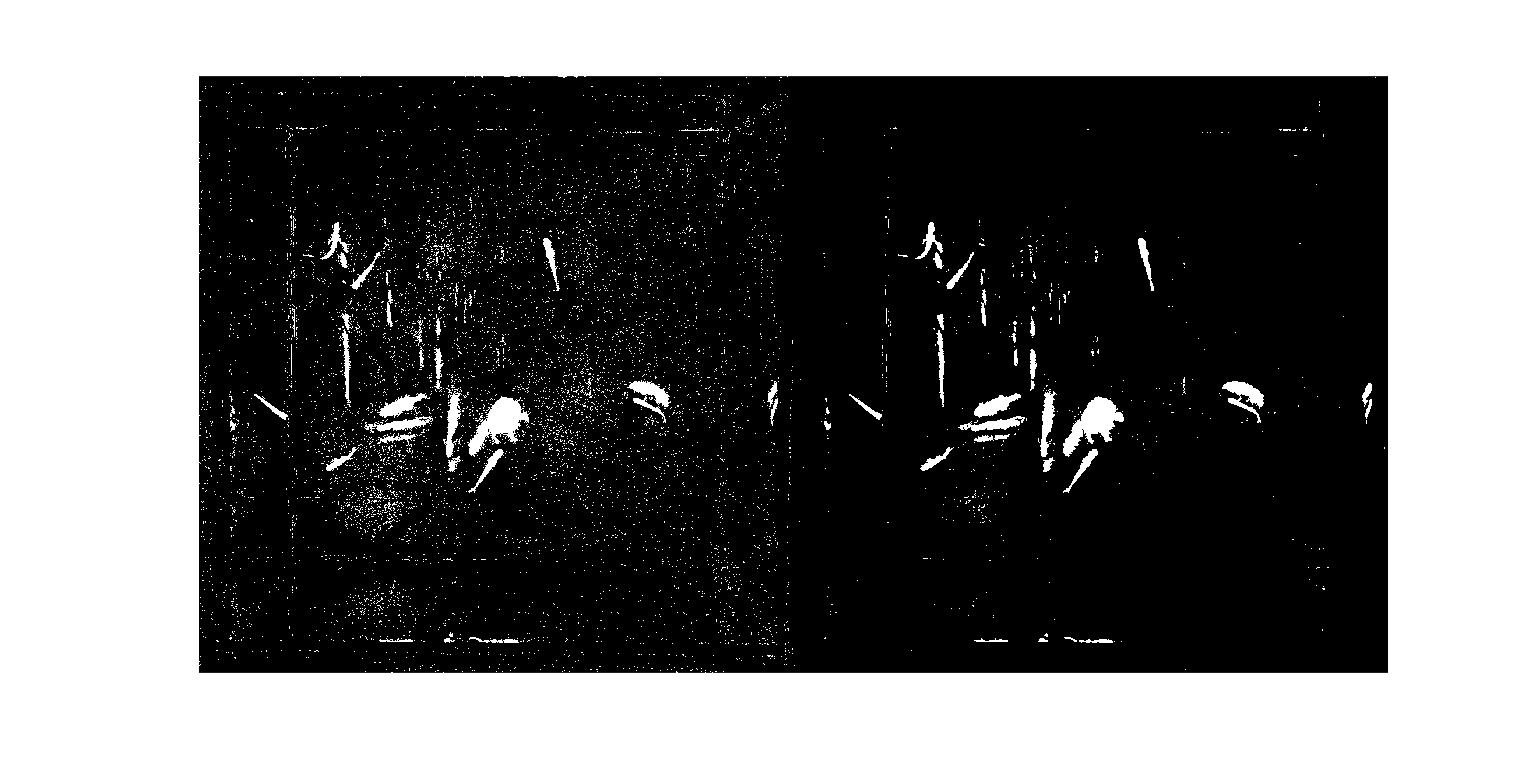

image4 = medfilt2(image3,[5,5]);
imshowpair(image3,image4,'montage');

## Mark Out Skeleton

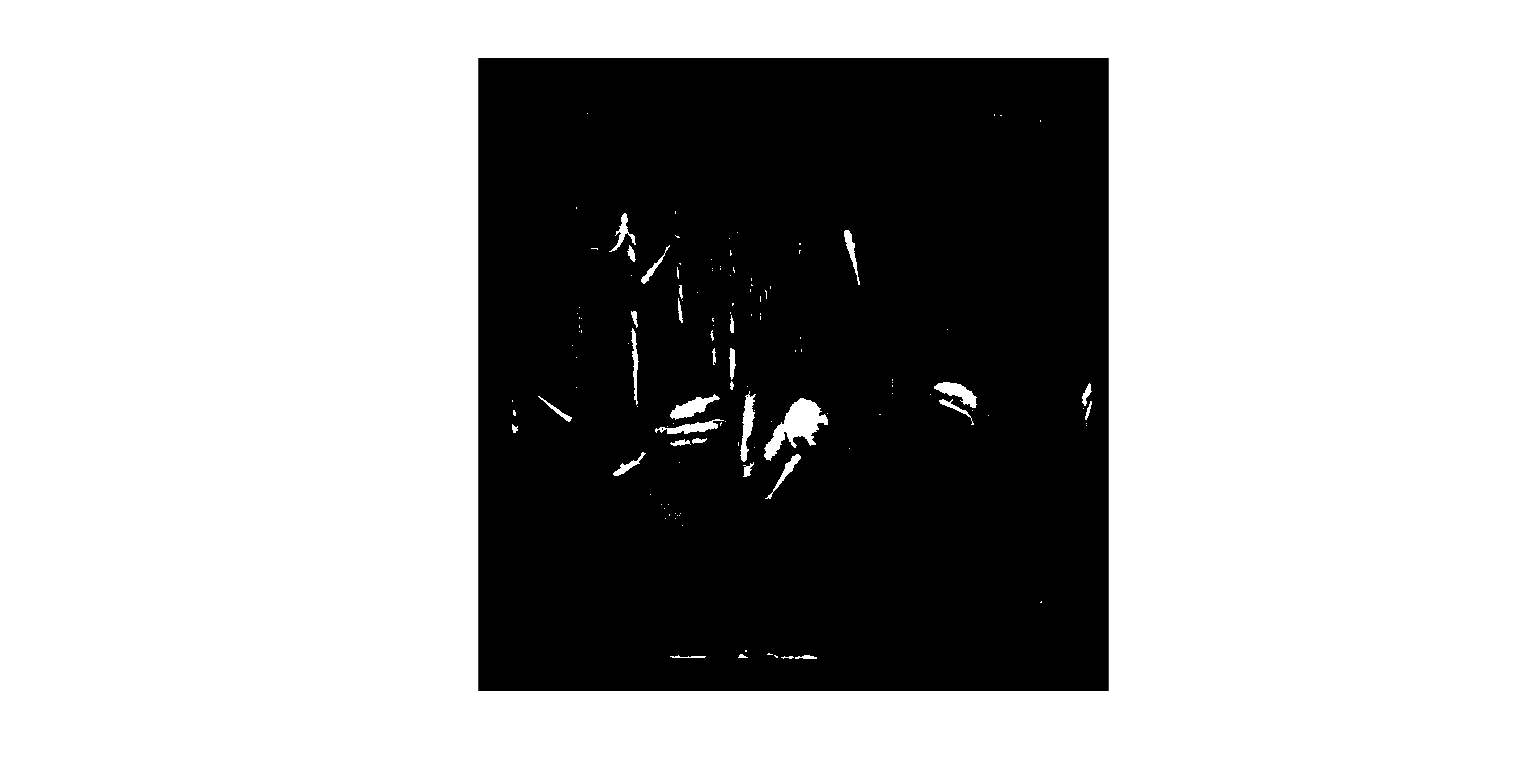

[ske, r] = skeleton(image4);
imshow(r);

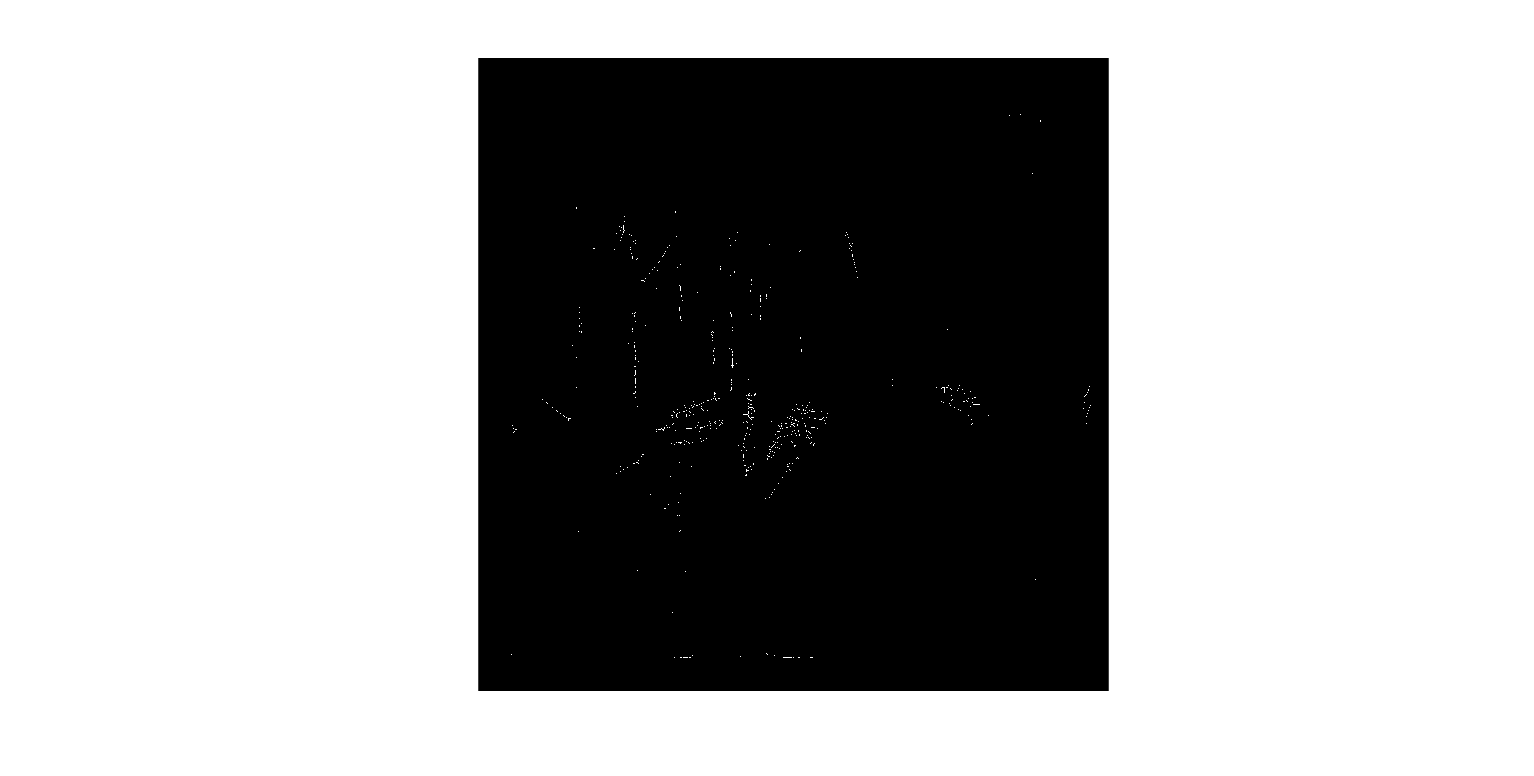

mainske = bwmorph(ske > 10, 'thin', inf);
imshow(mainske);

[d, ep, jp] = skeanalysis(mainske);
figure();imshow(image);hold on;

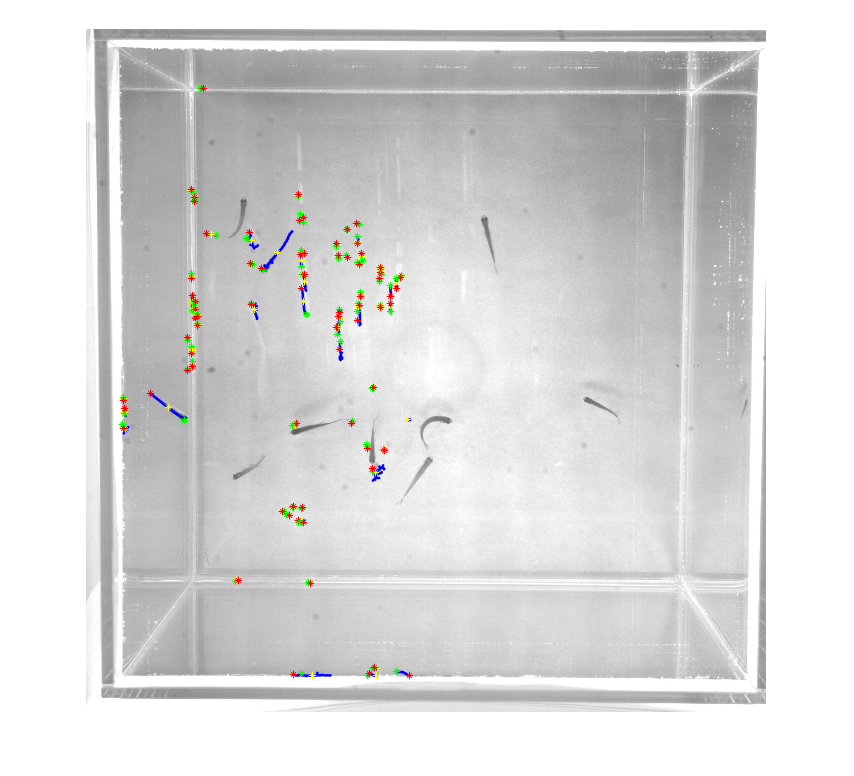

Index exceeds matrix dimensions.

Error in skemark (line 41)
           endpoint2 = endpoint(2, :);

skemark(mainske, ske, ep, jp, r);